- Create a cell array called ‘myCell’ where the first element is a random 3 x 4 matrix of integers, the second element is a vector with 200 elements ranging from -10 to 10, and the third element is a string of your choice.

mycell = {randi([1, 100], 3, 4), linspace(-10, 10, 200), "hello"}

mycell = 1×3 cell array
    {3×4 double}    {[-10 -9.8995 -9.7990 -9.6985 -9.5980 -9.4975 -9.3970 -9.2965 -9.1960 -9.0955 -8.9950 -8.8945 -8.7940 -8.6935 -8.5930 -8.4925 -8.3920 -8.2915 -8.1910 -8.0905 -7.9899 -7.8894 -7.7889 -7.6884 -7.5879 -7.4874 -7.3869 -7.2864 -7.1859 -7.0854 -6.9849 -6.8844 -6.7839 -6.6834 -6.5829 -6.4824 -6.3819 -6.2814 -6.1809 -6.0804 -5.9799 -5.8794 -5.7789 -5.6784 -5.5779 -5.4774 -5.3769 -5.2764 -5.1759 -5.0754 -4.9749 -4.8744 -4.7739 -4.6734 -4.5729 -4.4724 -4.3719 -4.2714 -4.1709 -4.0704 -3.9698 -3.8693 -3.7688 -3.6683 -3.5678 -3.4673 -3.3668 -3.2663 -3.1658 -3.0653 -2.9648 -2.8643 -2.7638 -2.6633 -2.5628 -2.4623 -2.3618 -2.2613 -2.1608 -2.0603 -1.9598 -1.8593 -1.7588 -1.6583 -1.5578 -1.4573 -1.3568 -1.2563 -1.1558 -1.0553 -0.9548 -0.8543 -0.7538 -0.6533 -0.5528 -0.4523 -0.3518 -0.2513 -0.1508 -0.0503 0.0503 0.1508 0.2513 0.3518 0.4523 0.5528 0.6533 0.7538 0.8543 0.9548 1.0553 1.1558 1.2563 1.3568 1.4573 1.5578 1.6583 1.7588 1.8593 1.9598 2.0603 2.1608 2.26

2. Request user input for indexes of an element in the 3 x 4 matrix. Your code should check that the user entered a valid pair of numbers and display a warning message if not.

rowInput = input("Input your row: ");
colInput = input("Input your column: ");
mat = mycell{1};
disp(mat);

    52    16    75    32
    89    20    83    54
    59    41    79     9



if isnumeric(colInput) && isnumeric(rowInput) && isscalar(colInput) && isscalar(rowInput)...
&& colInput >= 1 && colInput <= 4 && rowInput >= 1 && rowInput <= 3
    selectedElement = mat(rowInput, colInput);
    disp(selectedElement);
else
    disp('Invalid input');
end

     9



3. Create a new vector that is the vector in the cell array multiplied by the number in the matrix specified by the user, then insert this new vector as the third element of the cell array and shift the previous third element (string) to the fourth position of the cell array.

vect = mycell{2};
newVect = vect*selectedElement;
disp(vect);

  -10.0000   -9.8995   -9.7990   -9.6985   -9.5980   -9.4975   -9.3970   -9.2965   -9.1960   -9.0955   -8.9950   -8.8945   -8.7940   -8.6935   -8.5930   -8.4925   -8.3920   -8.2915   -8.1910   -8.0905   -7.9899   -7.8894   -7.7889   -7.6884   -7.5879   -7.4874   -7.3869   -7.2864   -7.1859   -7.0854   -6.9849   -6.8844   -6.7839   -6.6834   -6.5829   -6.4824   -6.3819   -6.2814   -6.1809   -6.0804   -5.9799   -5.8794   -5.7789   -5.6784   -5.5779   -5.4774   -5.3769   -5.2764   -5.1759   -5.0754   -4.9749   -4.8744   -4.7739   -4.6734   -4.5729   -4.4724   -4.3719   -4.2714   -4.1709   -4.0704   -3.9698   -3.8693   -3.7688   -3.6683   -3.5678   -3.4673   -3.3668   -3.2663   -3.1658   -3.0653   -2.9648   -2.8643   -2.7638   -2.6633   -2.5628   -2.4623   -2.3618   -2.2613   -2.1608   -2.0603   -1.9598   -1.8593   -1.7588   -1.6583   -1.5578   -1.4573   -1.3568   -1.2563   -1.1558   -1.0553   -0.9548   -0.8543   -0.7538   -0.6533   -0.5528   -0.4523   -0.3518   -0.2513   -0.1508   -0.0503

disp(newVect);

  -90.0000  -89.0955  -88.1910  -87.2864  -86.3819  -85.4774  -84.5729  -83.6683  -82.7638  -81.8593  -80.9548  -80.0503  -79.1457  -78.2412  -77.3367  -76.4322  -75.5276  -74.6231  -73.7186  -72.8141  -71.9095  -71.0050  -70.1005  -69.1960  -68.2915  -67.3869  -66.4824  -65.5779  -64.6734  -63.7688  -62.8643  -61.9598  -61.0553  -60.1508  -59.2462  -58.3417  -57.4372  -56.5327  -55.6281  -54.7236  -53.8191  -52.9146  -52.0101  -51.1055  -50.2010  -49.2965  -48.3920  -47.4874  -46.5829  -45.6784  -44.7739  -43.8693  -42.9648  -42.0603  -41.1558  -40.2513  -39.3467  -38.4422  -37.5377  -36.6332  -35.7286  -34.8241  -33.9196  -33.0151  -32.1106  -31.2060  -30.3015  -29.3970  -28.4925  -27.5879  -26.6834  -25.7789  -24.8744  -23.9698  -23.0653  -22.1608  -21.2563  -20.3518  -19.4472  -18.5427  -17.6382  -16.7337  -15.8291  -14.9246  -14.0201  -13.1156  -12.2111  -11.3065  -10.4020   -9.4975   -8.5930   -7.6884   -6.7839   -5.8794   -4.9749   -4.0704   -3.1658   -2.2613   -1.3568   -0.4523

mycell{4} = mycell{3};
mycell{3} = newVect;

4. Plot the 2 vectors from your cell array against each other in one line of code.

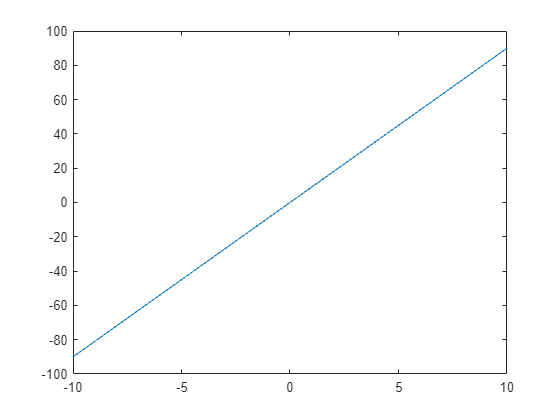

x = mycell{2};
y = mycell{3};
plot(x, y);

5. Create a structure called myStruct to save the following data:

myStruct = struct('Name', {'Harry', 'Georgia', 'Elizabeth'}, 'Age', {36, 21, 78}, 'Height_cm', {170, 181, 158}, 'Mass_kg', {80, 70, 65});

6. Change Georgia’s mass to be 68 kg.	

myStruct(2).Mass_kg = 68;

7. Add an extra person to the data with the following details: Name, Lily; Age, 24; Height, 162 cm; Mass, 60 kg.	

myStruct(4).Name = 'Lily';
myStruct(4).Age = 24;
myStruct(4).Height_cm = 162;
myStruct(4).Mass_kg = 60;

8. Using one line of code, calculate the mean height of the group.

disp(mean([myStruct.Height_cm]))

  167.7500



9. BMI is given by Mass (kg) divided by Height (metres) squared. Calculate the BMI of each person in the group and make a new field in your structure that saves this data for each person.

for i = 1:length(myStruct)
    bmi = myStruct(i).Mass_kg/(myStruct(i).Height_cm/100)^2;
    myStruct(i).BMI = bmi;
end

10. Use the sprintf function to display the names of the people in the group along with their age, height, mass and BMI displaying each value to 2 decimal places). 

for i = 1:length(myStruct)
    sprintf('Name: %s Age: %d Height: %.2f cm. Mass: %.2f BMI: %.2f', myStruct(i).Name, myStruct(i).Age, myStruct(i).Height_cm, myStruct(i).Mass_kg, myStruct(i).BMI)
end

ans = 'Name: Harry Age: 36 Height: 170.00 cm. Mass: 80.00 BMI: 27.68'

ans = 'Name: Georgia Age: 21 Height: 181.00 cm. Mass: 68.00 BMI: 20.76'

ans = 'Name: Elizabeth Age: 78 Height: 158.00 cm. Mass: 65.00 BMI: 26.04'

ans = 'Name: Lily Age: 24 Height: 162.00 cm. Mass: 60.00 BMI: 22.86'

11. Write a script that displays the number 12345.987654321 in the following formats (include leading 0’s if the width is longer than the number):

(a) Width 10 precision 3.

(b) Width 10 precision 6.

(c) Width 8 precision 6.

(d) Width 14 precision 6.

(e) What happens if you use a higher precision than there are decimal places (e.g. precision 12)?

number = 12345.987654321;
fprintf('(a) %010.3f', number);

(a) 012345.988

fprintf('(b) %010.6f', number);

(b) 12345.987654

12. Write a script that finds and displays the largest *x* that can be input to the exponential function (*ex*) before an infinite result is reached.

x = 1;
while exp(x) ~= inf
    x = x + 1;
end
disp(x-1);

   709



13. Write a script that asks the user for 2 inputs. Prompt the user for a random sentence. Then prompt the user for a letter of the alphabet. Your script should then display how many times that letter appears in their sentence and lists the words in which it appears.

sentence1 = input('write a random sentence: ', 's');
word1 = input('pick a letter of matching words is 2: ', 's');
%????????????????????????????????????????????????????????

14. Load the datafile “DOB.mat” into the Matlab workspace then create a categorical array of the generations defined as follows:

“Boomer” born in 1946-1964

“Gen X” born in 1965-1980

“Millennials” born in 1981-1996

“Gen Z” born in 1997-1997-2012

“Gen A” born in 2012-present

**(Hint: Use the discretize() function)**

Display how many of each generation are in the data set then create a table that contains columns for each day, month, date, year and generation. 

Display the first 10 table entries. 

Now display the date of births of all Gen A. 

Lastly, locate all people born in July and display the corresponding year of their births, the day on which they were born, and their generation.

load DOB.mat;



15. The following code performs some tasks in Matlab using a for loop. Vectorise the code to produce the same result without using any loops.

16. Create a random 4 x 4 matrix, ***A***, with values between 0 and 1 then swap the 2nd and 4th row using one line of code

A = rand(4, 4);
disp(A);

    0.8909    0.1493    0.8143    0.1966
    0.9593    0.2575    0.2435    0.2511
    0.5472    0.8407    0.9293    0.6160
    0.1386    0.2543    0.3500    0.4733



A([2, 4], :) = A([4,2], :);
disp(A);

    0.8909    0.1493    0.8143    0.1966
    0.1386    0.2543    0.3500    0.4733
    0.5472    0.8407    0.9293    0.6160
    0.9593    0.2575    0.2435    0.2511



17. Using the matrix, ***A***, from Q16 now swap the 1st and 4th columns using one line of code.

disp(A);

    0.8909    0.1493    0.8143    0.1966
    0.1386    0.2543    0.3500    0.4733
    0.5472    0.8407    0.9293    0.6160
    0.9593    0.2575    0.2435    0.2511



A(:,[1,4]) = A(:,[4,1]);
disp(A);

    0.1966    0.1493    0.8143    0.8909
    0.4733    0.2543    0.3500    0.1386
    0.6160    0.8407    0.9293    0.5472
    0.2511    0.2575    0.2435    0.9593



18. Using one line of code, set every value of ***A*** that is greater than 0.5 equal to 7.

disp(A);

    0.1966    0.1493    0.8143    0.8909
    0.4733    0.2543    0.3500    0.1386
    0.6160    0.8407    0.9293    0.5472
    0.2511    0.2575    0.2435    0.9593



disp(A(A>0.5));

    0.6160
    0.8407
    0.8143
    0.9293
    0.8909
    0.5472
    0.9593



A(A>0.5)=7;
disp(A)

    0.1966    0.1493    7.0000    7.0000
    0.4733    0.2543    0.3500    0.1386
    7.0000    7.0000    7.0000    7.0000
    0.2511    0.2575    0.2435    7.0000



19. Create a 4 x 7 matrix, ***B***, of random integers between 10 and 50 then using one line of code set every value of ***B*** that is both greater than 20 and less than 40 equal to 0 (***Hint:*** Use the element-wise logical operators, ‘&’ and ‘|’).

B = randi([10, 50], 4, 7);
disp(B);

    45    44    26    17    47    23    41
    33    35    13    19    48    46    25
    32    24    19    27    30    25    19
    15    31    15    12    30    14    26



B(B>20 & B< 40) = 0;
disp(B);

    45    44     0    17    47     0    41
     0     0    13    19    48    46     0
     0     0    19     0     0     0    19
    15     0    15    12     0    14     0



20. Using one line of code insert the column vector [3 -2 4 8]T in between the 2nd and 3rd columns of ***B***.

B = [B(:, 1:2), [3 ;-2 ;4 ;8], B(:, 3:end)];
disp(B);

    45    44     3     0    17    47     0    41
     0     0    -2    13    19    48    46     0
     0     0     4    19     0     0     0    19
    15     0     8    15    12     0    14     0



21. Write a script that creates an anonymous function for the function *f*(*x*) = *x*2 – 3*x* + 1 then plots it between -4 and 4 with a grid.

f = @(x) x.^2 - 3*x + 1;
x = linspace(-4, 4, 100);
y = f(x)

y =    29.0000   28.1176   27.2483   26.3921   25.5489   24.7188   23.9017   23.0977   22.3068   21.5289   20.7641   20.0123   19.2736   18.5480   17.8354   17.1359   16.4494   15.7760   15.1157   14.4684   13.8342   13.2130   12.6049   12.0099   11.4279   10.8590   10.3031    9.7603    9.2306    8.7139    8.2103    7.7197    7.2422    6.7778    6.3264    5.8881    5.4628    5.0506    4.6515    4.2654    3.8924    3.5324    3.1855    2.8516    2.5309    2.2231    1.9285    1.6469    1.3783    1.1228


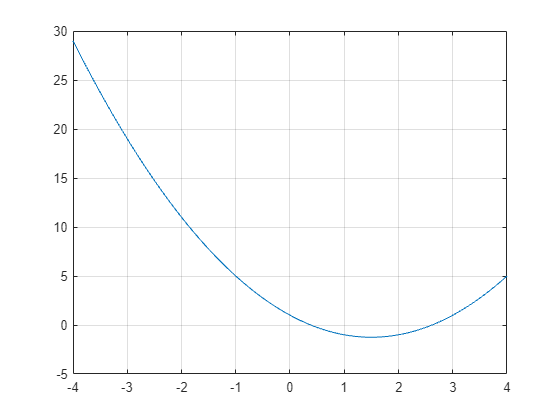

plot(x, y);
grid on